clear;
rmdir('.\DataSet\', 's');
mkdir('.\DataSet\');

% 配置
config;
%-----------------------------
% 产生信号
source;
tag;
global y_sig;
y_sig = y_source .* y_tag;

global Length;
global Width;

## 房间内的随机点


N_inside = 8;
x = Width * rand(1, N_inside);
y = Length * rand(1, N_inside);

% 计算三个距离
[d1, d2, d3] = xy2d(x, y);

single_run(d1, d2, d3, false, 'inside');

delta t is
   1.0e-07 *

    0.0496    0.0608    0.0109    0.0852    0.1631    0.0207    0.0115    0.0190



## 房间外的随机点

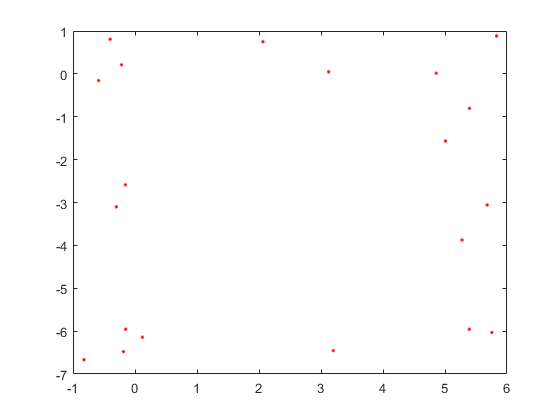

% 1/4 的数量
N_outside = 5;
x0 = rand(4, N_outside);
y0 = rand(4, N_outside);

x0 = [((Width / 2 + 1) * x0(:, 1:floor(N_outside / 2)))   (Width / 2 + x0(:, round(N_outside / 2) : end))];
y0 = [(Length / 2 + y0(:, 1:floor(N_outside / 2)))  ((Length / 2 + 1) * y0(:, round(N_outside / 2): end))];

x0(1,:) = -1 * x0(1, :);
x0(3,:) = -1 * x0(3, :);
y0(3,:) = -1 * y0(3, :);
y0(4,:) = -1 * y0(4, :);

% 坐标原点
x0 = x0 - (-1) * (Width / 2) * ones(size(x0));
y0 = y0 - 1 * (Length / 2) * ones(size(y0));

% 画出散点
% TODO: bugfix --- 点都集中在四个角落了，需要分散到边边上
figure; plot(x0,y0,'r.');


% 计算三个距离
[d1_0, d2_0, d3_0] = xy2d(x0, y0);
single_run(d1_0, d2_0, d3_0, false, 'outside');

delta t is
   1.0e-07 *

    0.0720    0.0248    0.0357    0.0521    0.1814
    0.2235    0.1357    0.2814    0.2752    0.2589
    0.4126    0.4497    0.2146    0.4349    0.4003
    0.5243    0.4713    0.3942    0.5070    0.3743





% 保存样本点
filename = '.\DataSet\sample.mat'

filename = '.\DataSet\sample.mat'

save(filename, 'N_inside', 'N_outside', 'x', 'y', 'd1', 'd2', 'd3', 'x0', 'y0', 'd1_0', 'd2_0', 'd3_0');

## 数据预处理

% [] = preproc(filename, i, draw, isBeacon)
for i=1: N_inside
    preproc('i_sig_rx', i, false, 'inside');
end

% outside
for i=1: 4 * N_outside
    preproc('o_sig_rx', i, false, 'outside');
end